# maxwellCMF2CIE

**Deriving the cone fundamentals: a subspace intersection method - Figure 1**

Compare Maxwell CMFs with the CIE XYZ and the Stockman fundamentals.

We compare the CMFs reported by Maxwell in Tables VI and IX of the 1860 paper with the Stockman fundamentals. This confirms and slightly extends the analysis performed by Judd in 1966, who used the XYZ curves. We do a bit better by adjusting the Judd wavelength estimates with an offset of about 10. The reason for the shift is explained in the comments below.

See also maxwellMatch - That script contains a new analysis. It computes directly from the matches in Table IV to the CMFs and shows a good match, as well.

See also

- maxwellJuddWave.m     - Explain Judd's wavelength estimate from Maxwell's data

- maxwellDataCMF.mlx     - Writes out the Maxwell 1860 data 

- maxwellMatchWhite.mlx -  Calculates from the matches, directly

## Initialize ISET

ieInit;

## Maxwell observers' CMFs

From the data directory of this repository, the two observers from the Maxwell 1860 paper.

obsJ = load("maxwellCMF_obsJ");
obsK = load('maxwellCMF_obsK');

We think Judd's estimates of Maxwell's wavelengths are off by ~10 nm. The reason may be that there was a slight, constant offset, in the position that Maxwell identified on his apparatus. We have no specific evidence for this, but ncluding this adjustment brings Maxwell's data in excellent alignment with the modern data, particularly in the short wavelength part of the spectrum.

juddAdjust = 10;

## Transform Maxwell's CMFs to CIE XYZ and plot the comparison

Start with Observer K

Adjust the wavelengths

waveK = obsK.wave - juddAdjust;
XYZK = ieReadSpectra('XYZEnergy',waveK);
RGB = [obsK.R(:),obsK.G(:),obsK.B(:)];

Find the linear transform from the CMF to CIE XYZ.  The formulat is


$$xyz \approx RGB ~ L \\
L = RGB^{-1} xyz \\
estXYZ = RGB ~ L$$


L = RGB\XYZK;
XYZ_estK = RGB*L;

## Compare the two observers RGB to the CIE XYZ, as in Judd

Here is the graph for the fits of the Observer K RGB data to the XYZ functions

ieNewGraphWin([],'big');
tiledlayout(2,2);

nexttile;
plot(waveK,XYZ_estK); hold on;
plot(waveK,XYZK,'LineStyle','--');
xlabel('Wavelength (nm)')
legend('XYZ','','','Maxwell ObsK fit');


 Now for Observer J

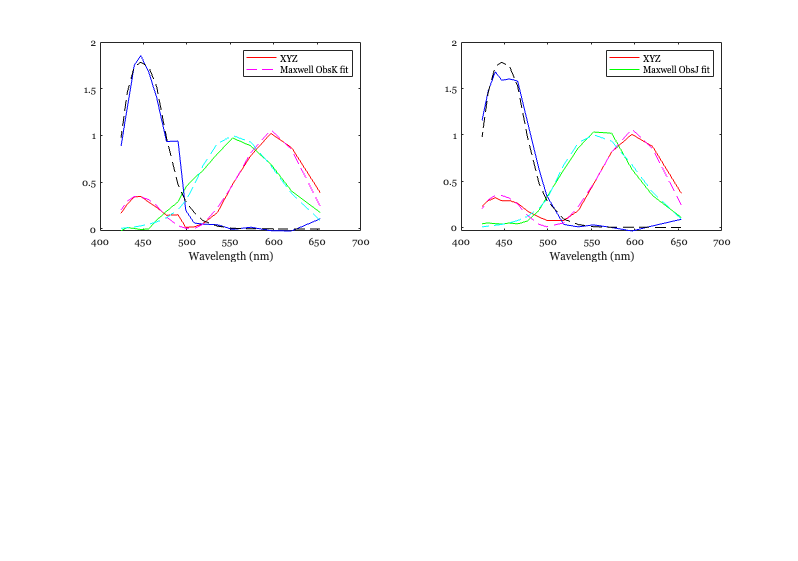

waveJ = obsJ.wave - juddAdjust;
XYZJ = ieReadSpectra('XYZEnergy',waveJ);
RGB = [obsJ.R(:),obsJ.G(:),obsJ.B(:)];
L = RGB\XYZJ;
XYZ_estJ = RGB*L;

nexttile;
plot(waveJ,XYZ_estJ); hold on;
plot(waveJ,XYZJ,'LineStyle','--');
xlabel('Wavelength (nm)')
legend('XYZ','Maxwell ObsJ fit');

## Transform Maxwell's CMF data to Stockman-Sharpe cone fundamentals 

Same idea, but this time we compare with stockman-sharpe

Maxwell's CMFs into alighnment with the Stockman-Sharpe cone fundamentals.

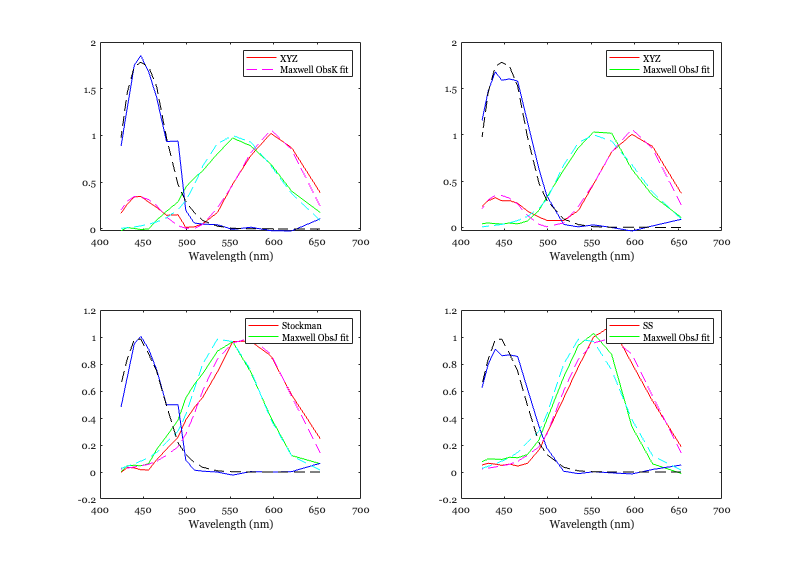

wave = obsK.wave - juddAdjust;
SS = ieReadSpectra('StockmanEnergy',wave);
RGB = [obsK.R(:),obsK.G(:),obsK.B(:)];
L = pinv(RGB)*SS;
SS_est = RGB*L;

nexttile;
plot(wave,SS_est); hold on;
plot(wave,SS,'LineStyle','--');
xlabel('Wavelength (nm)')
legend('Stockman','Maxwell ObsJ fit');

wave = obsJ.wave - juddAdjust;
SS = ieReadSpectra('StockmanEnergy',wave);
RGB = [obsJ.R(:),obsJ.G(:),obsJ.B(:)];
L = pinv(RGB)*SS;
SS_est = RGB*L;

nexttile;
plot(wave,SS_est); hold on;
plot(wave,SS,'LineStyle','--');
xlabel('Wavelength (nm)')
legend('SS','Maxwell ObsJ fit');

## Make a verison of the figure for a slide (color)

This a linear transform that takes the Maxwell and the Stockman-Sharpe curves to the CIE XYZ representation

Run this after the sections above, as it uses variables created there.

Almost all of this section is just formatting the figure.

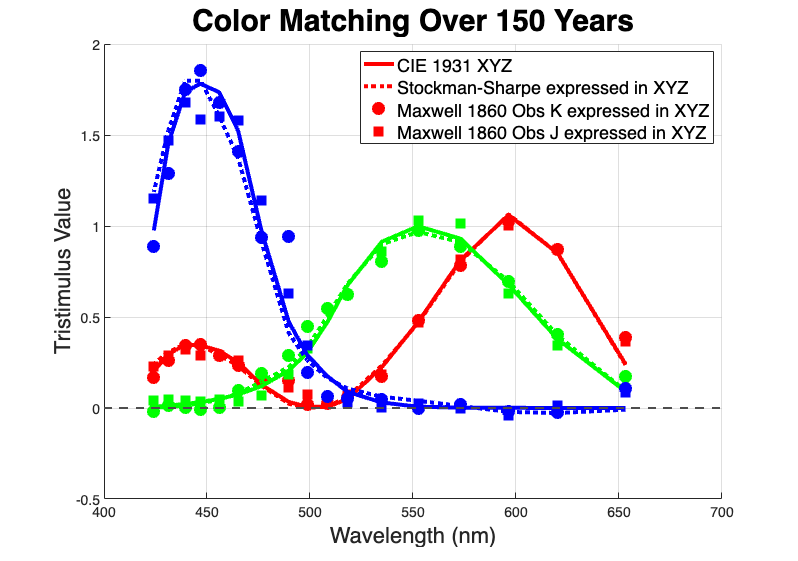

SSK = ieReadSpectra('StockmanEnergy',waveK);
L = pinv(SSK)*XYZK;
XYZK_SSest = SSK*L;

ieNewGraphWin([],'big'); clf; hold on;
set(gca,'FontName','Helvetica','FontSize',26);
plot(waveK,XYZK(:,1),'-','Color','r','LineWidth',4);
plot(waveK,XYZK_SSest(:,1),':','Color','r','LineWidth',4);
set(gca,'FontName','Helvetica','FontSize',14);
plot(waveK,XYZ_estK(:,1),'o','Color','r','MarkerFaceColor','r','MarkerSize',12);
plot(waveJ,XYZ_estJ(:,1),'s','Color','r','MarkerFaceColor','r','MarkerSize',12);

plot(waveK,XYZK(:,2),'-','Color','g','LineWidth',4);
plot(waveK,XYZK_SSest(:,2),':','Color','g','LineWidth',4);
plot(waveK,XYZ_estK(:,2),'o','Color','g','MarkerFaceColor','g','MarkerSize',12);
plot(waveJ,XYZ_estJ(:,2),'s','Color','g','MarkerFaceColor','g','MarkerSize',12);

plot(waveK,XYZK(:,3),'-','Color','b','LineWidth',4);
plot(waveK,XYZK_SSest(:,3),':','Color','b','LineWidth',4);
plot(waveK,XYZ_estK(:,3),'o','Color','b','MarkerFaceColor','b','MarkerSize',12);
plot(waveJ,XYZ_estJ(:,3),'s','Color','b','MarkerFaceColor','b','MarkerSize',12);

xlabel('Wavelength (nm)','FontName','Helvetica','FontSize',22);
ylabel('Tristimulus Value','FontName','Helvetica','FontSize',22);
xaxisLine;
legend({'CIE 1931 XYZ', 'Stockman-Sharpe expressed in XYZ', 'Maxwell 1860 Obs K expressed in XYZ', 'Maxwell 1860 Obs J expressed in XYZ'},'FontName','Helvetica','FontSize',18);
title('Color Matching Over 150 Years','FontName','Helvetica','FontSize',30);

## Create a form of the same plot as a monochrome figure

Almost all of this section is just formatting the figure.

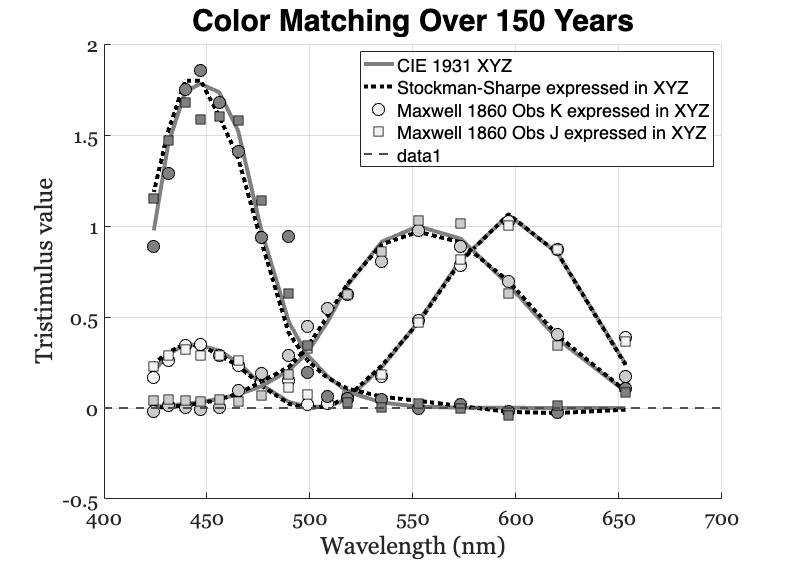

marker = [ 0.95 0.8 0.5];   % Gray levels of the subject marker data

ieNewGraphWin([],'big'); clf; hold on;
set(gca,'FontName','Helvetica','FontSize',26);
plot(waveK,XYZK(:,1),'-','Color',[1 1 1]*0.5,'LineWidth',4);
plot(waveK,XYZK_SSest(:,1),':','Color',[1 1 1]*0.0,'LineWidth',4);
set(gca,'FontName','Helvetica','FontSize',14);
plot(waveK,XYZ_estK(:,1),'o','Color',[1 1 1]*0,'MarkerFaceColor',[1 1 1]*marker(1),'MarkerSize',12);
plot(waveJ,XYZ_estJ(:,1),'s','Color',[1 1 1]*0,'MarkerFaceColor',[1 1 1]*marker(1),'MarkerSize',12);

plot(waveK,XYZK(:,2),'-','Color',[1 1 1]*0.5,'LineWidth',4);
plot(waveK,XYZK_SSest(:,2),':','Color',[1 1 1]*0,'LineWidth',4);
plot(waveK,XYZ_estK(:,2),'o','Color',[1 1 1]*0,'MarkerFaceColor',[1 1 1]*marker(2),'MarkerSize',12);
plot(waveJ,XYZ_estJ(:,2),'s','Color',[1 1 1]*0,'MarkerFaceColor',[1 1 1]*marker(2),'MarkerSize',12);

plot(waveK,XYZK(:,3),'-','Color',[1 1 1]*0.5,'LineWidth',4);
plot(waveK,XYZK_SSest(:,3),':','Color',[1 1 1]*0,'LineWidth',4);
plot(waveK,XYZ_estK(:,3),'o','Color',[1 1 1]*0,'MarkerFaceColor',[1 1 1]*marker(3),'MarkerSize',12);
plot(waveJ,XYZ_estJ(:,3),'s','Color',[1 1 1]*0,'MarkerFaceColor',[1 1 1]*marker(3),'MarkerSize',12);

fSizeTicks = 20;
fSizeLabel = 24;
fontName = 'Georgia';
set(gca,'FontSize',fSizeTicks,'FontName',fontName);
tmp = xlabel('Wavelength (nm)','FontName',fontName,'FontSize',fSizeLabel);
ylabel('Tristimulus value','FontName',fontName,'FontSize',fSizeLabel);

legend({'CIE 1931 XYZ', 'Stockman-Sharpe expressed in XYZ', 'Maxwell 1860 Obs K expressed in XYZ', 'Maxwell 1860 Obs J expressed in XYZ'},'FontName','Helvetica','FontSize',18);
title('Color Matching Over 150 Years','FontName','Helvetica','FontSize',30);
xaxisLine;